% Parachute Code V4
% Latest Update: 11/21/25



% Index
% Parachute Size and Drag
% Parachute Inflation
% Parachute Shock
% Canopy Size Comparisson
% Wind Effect on Landing

% Terms:
% Object 1 is Strobing Beacon
% Object 2 is Water Bottle
% Wind Direction: North to South

clc 
clear all
close all

% Parachute Size and Drag
clc
clear all
close all

% Object 1:
% --- USER INPUTS -----------------------------------------
m = 0.155;           % mass [kg]
h0 = 160 * 0.3048; % drop height [m]
Cd = 0.75;         % drag coefficient (solid-cloth, flat canopy)
rho = 1.225;       % air density at sea level [kg/m^3]
Vt = 5;            % desired terminal velocity [m/s]
g = 9.81;          % gravity [m/s^2]
% --- CALCULATIONS ----------------------------------------
W = m * g;                                % weight [N]
A = 2 * W / (rho * Cd * Vt^2);            % required canopy area [m^2]
D = sqrt(4 * A / pi);                     % equivalent canopy diameter [m]

% Estimate descent time (assuming steady Vt)
t_descent = h0 / Vt;                      % seconds

% --- OUTPUT RESULTS --------------------------------------
fprintf('\n--- PARACHUTE DESIGN ESTIMATE ---\n');


--- PARACHUTE DESIGN ESTIMATE ---


fprintf('Object mass: %.3f kg\n', m);

Object mass: 0.155 kg


fprintf('Drop height: %.1f m (%.0f ft)\n', h0, h0/0.3048);

Drop height: 48.8 m (160 ft)


fprintf('Desired terminal velocity: %.1f m/s\n', Vt);

Desired terminal velocity: 5.0 m/s


fprintf('Parachute drag coefficient Cd: %.2f\n', Cd);

Parachute drag coefficient Cd: 0.75


fprintf('Air density: %.3f kg/m^3\n', rho);

Air density: 1.225 kg/m^3


fprintf('\nRequired canopy area: %.3f m^2\n', A);


Required canopy area: 0.132 m^2


fprintf('Equivalent canopy diameter: %.3f m (%.2f ft)\n', D, D/0.3048);

Equivalent canopy diameter: 0.411 m (1.35 ft)


fprintf('Approximate descent time: %.1f s\n', t_descent);

Approximate descent time: 9.8 s



%==========================================================

% Object 2:
% --- USER INPUTS -----------------------------------------
m = 0.255;           % mass [kg]
h0 = 160 * 0.3048; % drop height [m]
Cd = 0.75;         % drag coefficient (solid-cloth, flat canopy)
rho = 1.225;       % air density at sea level [kg/m^3]
Vt = 5;            % desired terminal velocity [m/s]
g = 9.81;          % gravity [m/s^2]
% --- CALCULATIONS ----------------------------------------
W = m * g;                                % weight [N]
A = 2 * W / (rho * Cd * Vt^2);            % required canopy area [m^2]
D = sqrt(4 * A / pi);                     % equivalent canopy diameter [m]

% Estimate descent time (assuming steady Vt)
t_descent = h0 / Vt;                      % seconds

% --- OUTPUT RESULTS --------------------------------------
fprintf('\n--- PARACHUTE DESIGN ESTIMATE ---\n');


--- PARACHUTE DESIGN ESTIMATE ---


fprintf('Object mass: %.3f kg\n', m);

Object mass: 0.255 kg


fprintf('Drop height: %.1f m (%.0f ft)\n', h0, h0/0.3048);

Drop height: 48.8 m (160 ft)


fprintf('Desired terminal velocity: %.1f m/s\n', Vt);

Desired terminal velocity: 5.0 m/s


fprintf('Parachute drag coefficient Cd: %.2f\n', Cd);

Parachute drag coefficient Cd: 0.75


fprintf('Air density: %.3f kg/m^3\n', rho);

Air density: 1.225 kg/m^3


fprintf('\nRequired canopy area: %.3f m^2\n', A);


Required canopy area: 0.218 m^2


fprintf('Equivalent canopy diameter: %.3f m (%.2f ft)\n', D, D/0.3048);

Equivalent canopy diameter: 0.527 m (1.73 ft)


fprintf('Approximate descent time: %.1f s\n', t_descent);

Approximate descent time: 9.8 s



%==========================================================

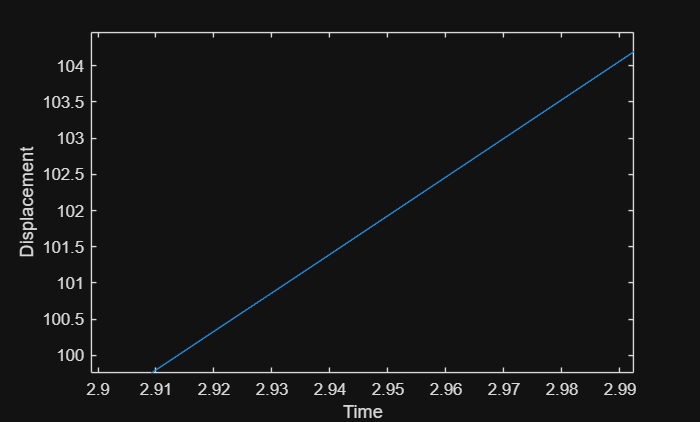

% Parachute Inflation
clc 
clear all
close all

syms v(t)

g = 9.81;
rho = 1.225;
AO = 0.00709;
CdO = 1.15;
m = 0.155;

ode = g - diff(v,t) == CdO*AO*rho*(v^2)/(2*m);
ic = v(0) == 0;
vsol(t) = dsolve(ode,ic);
ysol(t) = int(vsol)*3.28084;

fplot(ysol,[0 10]);
xlabel('Time')
ylabel('Displacement')


% Object 1:
%% ---- USER INPUTS --------------------------------------------------------
m       = 0.155;          % mass [kg]
Cd      = 0.75;           % fully deployed drag coefficient
CdO     = 1.15;           % Drag coefficient of a short cylinder 
AO      = .00709;         % Area of object in m^2
rho     = 1.225;          % air density [kg/m^3]
D       = 0.58;           % parachute diameter [m]
Vt_des  = 5;              % desired final velocity [m/s]
g       = 9.81;           % gravity [m/s^2]
cPC     = 4.4;            % permabilty constant of ripstop nylon [CFM]

%% ---- DERIVED PARAMETERS --------------------------------------------------
A = pi * (D/2)^2;         % canopy area
W = m * g;                % weight [N]

%% ---- SIMULATION PARAMETERS -----------------------------------------------

V0    = 15;              % velocity at deployment (downward, m/s)
T = (sqrt((W/A)*Cd))/(rho*V0); % Time inflation equation
t_inf = cPC*T;           % assumed inflation time [s]
dt = 0.001;               
t  = 0:dt:10;             
V  = zeros(size(t));      
V(1) = V0;                % velocity positive DOWNWARD

%% ---- SIMULATION LOOP ------------------------------------------------------
for i = 1:length(t)-1

    % --- Phase 1: Inflation (effective area grows from 0 → A)
    if t(i) < t_inf
        A_eff = A * (t(i)/t_inf)^2;   % quadratic growth
    else
        A_eff = A;
    end

    % Drag force (ALWAYS upward)
    Drag = 0.5 * rho * Cd * A_eff * V(i)^2;

    % Net acceleration (downward positive)
    % a = g - (Drag/m)
    a = g - Drag/m;

    % Update velocity
    V(i+1) = V(i) + a*dt;

    % Prevent bouncing upward: if drag > weight, velocity becomes upward
    if V(i+1) < 0
        V(i+1) = 0;
    end
end

%% ---- Determine key times --------------------------------------------------
t_inflation_complete = t_inf;

% Time when velocity first reaches desired terminal velocity
idx = find(V <= Vt_des, 1, 'first');

if ~isempty(idx)
    t_slowdown = t(idx);
else
    t_slowdown = NaN;
end

%% ---- OUTPUT RESULTS -------------------------------------------------------
fprintf('\n--- PARACHUTE DEPLOYMENT / SLOWDOWN MODEL (CORRECTED) ---\n');


--- PARACHUTE DEPLOYMENT / SLOWDOWN MODEL (CORRECTED) ---


fprintf('Parachute area: %.3f m^2\n', A);

Parachute area: 0.264 m^2


fprintf('Inflation completes at: %.3f s\n', t_inf);

Inflation completes at: 0.497 s



if ~isnan(t_slowdown)
    fprintf('Time to reach %.2f m/s terminal velocity: %.3f s\n', Vt_des, t_slowdown);
else
    fprintf('Desired velocity NOT reached within simulation window.\n');
end

Time to reach 5.00 m/s terminal velocity: 0.590 s



fprintf('Velocity at end of inflation: %.2f m/s\n', V(round(t_inf/dt)));

Velocity at end of inflation: 6.40 m/s


fprintf('Final velocity at t = 10 s: %.2f m/s\n', V(end));

Final velocity at t = 10 s: 3.54 m/s


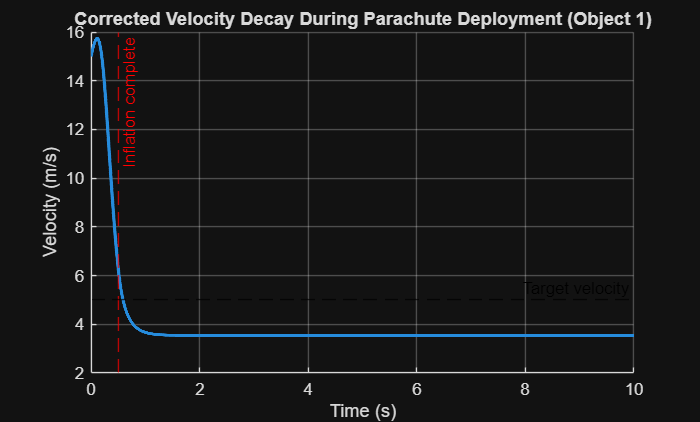


%% ---- PLOTS ----------------------------------------------------------------
figure; hold on; grid on
plot(t, V, 'LineWidth', 2);

xline(t_inf, '--r', 'Inflation complete');
yline(Vt_des, '--k', 'Target velocity');

xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Corrected Velocity Decay During Parachute Deployment (Object 1)');


% Object 2:%% ---- USER INPUTS --------------------------------------------------------
m       = 0.255;            % mass [kg]
Cd      = 0.75;           % fully deployed drag coefficient
rho     = 1.225;          % air density [kg/m^3]
D       = 0.58;           % parachute diameter [m]
Vt_des  = 5;              % desired final velocity [m/s]
V0      = 35;             % velocity at deployment (downward, m/s)
g       = 9.81;           % gravity [m/s^2]
cPC     = 4.4;            % premability constant of rip stop nylon [CFM]

%% ---- DERIVED PARAMETERS --------------------------------------------------
A = pi * (D/2)^2;         % canopy area
W = m * g;                % weight [N]

%% ---- SIMULATION PARAMETERS -----------------------------------------------
T = (sqrt((W/A)*Cd))/(rho*V0); % Time inflation equation
t_inf = cPC*T;           % assumed inflation time [s]
dt = 0.001;               
t  = 0:dt:10;             
V  = zeros(size(t));      
V(1) = V0;                % velocity positive DOWNWARD

%% ---- SIMULATION LOOP ------------------------------------------------------
for i = 1:length(t)-1

    % --- Phase 1: Inflation (effective area grows from 0 → A)
    if t(i) < t_inf
        A_eff = A * (t(i)/t_inf)^2;   % quadratic growth
    else
        A_eff = A;
    end

    % Drag force (ALWAYS upward)
    Drag = 0.5 * rho * Cd * A_eff * V(i)^2;

    % Net acceleration (downward positive)
    % a = g - (Drag/m)
    a = g - Drag/m;

    % Update velocity
    V(i+1) = V(i) + a*dt;

    % Prevent bouncing upward: if drag > weight, velocity becomes upward
    if V(i+1) < 0
        V(i+1) = 0;
    end
end

%% ---- Determine key times --------------------------------------------------
t_inflation_complete = t_inf;

% Time when velocity first reaches desired terminal velocity
idx = find(V <= Vt_des, 1, 'first');

if ~isempty(idx)
    t_slowdown = t(idx);
else
    t_slowdown = NaN;
end

%% ---- OUTPUT RESULTS -------------------------------------------------------
fprintf('\n--- PARACHUTE DEPLOYMENT / SLOWDOWN MODEL (CORRECTED) ---\n');


--- PARACHUTE DEPLOYMENT / SLOWDOWN MODEL (CORRECTED) ---


fprintf('Parachute area: %.3f m^2\n', A);

Parachute area: 0.264 m^2


fprintf('Inflation completes at: %.3f s\n', t_inf);

Inflation completes at: 0.273 s



if ~isnan(t_slowdown)
    fprintf('Time to reach %.2f m/s terminal velocity: %.3f s\n', Vt_des, t_slowdown);
else
    fprintf('Desired velocity NOT reached within simulation window.\n');
end

Time to reach 5.00 m/s terminal velocity: 0.827 s



fprintf('Velocity at end of inflation: %.2f m/s\n', V(round(t_inf/dt)));

Velocity at end of inflation: 14.90 m/s


fprintf('Final velocity at t = 10 s: %.2f m/s\n', V(end));

Final velocity at t = 10 s: 4.54 m/s


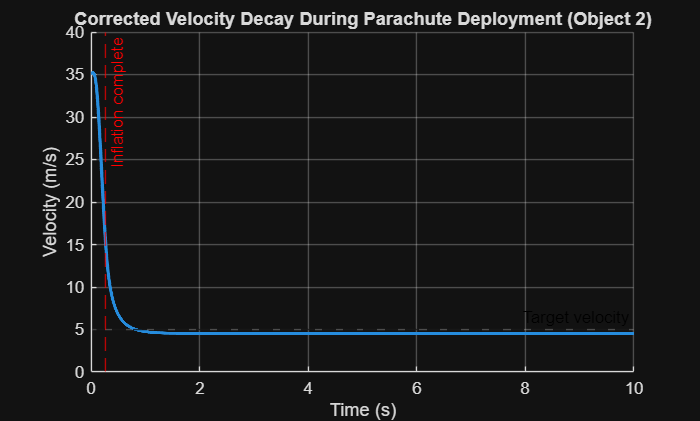


%% ---- PLOTS ----------------------------------------------------------------
figure; hold on; grid on
plot(t, V, 'LineWidth', 2);

xline(t_inf, '--r', 'Inflation complete');
yline(Vt_des, '--k', 'Target velocity');

xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Corrected Velocity Decay During Parachute Deployment (Object 2)');

% Parachute shock and slowdown

% Object 1:
%%---------------------- USER INPUTS ----------------------------

m = 0.155;                     % mass [kg]
h_drop = 160 * 0.3048;       % drop height [m]
desired_V = 5;               % desired terminal velocity (m/s)
Cd = 0.75;                   % drag coefficient
rho = 1.225;                 % air density
g = 9.81;                    % gravity

% NSWC-like inflation parameters
j = 6;                       % solid-cloth exponent
tau = 0;                     % initial area ratio (use 0)

%%---------------------- DERIVED VALUES -------------------------

W = m * g;

% Area required to achieve desired terminal velocity when fully inflated
%   A = 2W / (rho * Cd * V^2)
A = 2*W / (rho * Cd * desired_V^2);

% Equivalent diameter
D = sqrt(4*A/pi);

% Initial velocity at deployment (free fall from h_drop)
V0 = sqrt(2 * g * h_drop);

% Estimate inflation reference time t0 (NSWC style heuristic)
t0 = max(0.05, 2*W/(rho * V0 * Cd * A));

% Reference steady drag at incoming V0
Fs = 0.5 * rho * V0^2 * Cd * A;

%%---------------------- SIMULATION SETUP ------------------------

dt = 0.001;
t_end = 10;
time = 0:dt:t_end;
N = length(time);

V = zeros(1,N);
TFAC = zeros(1,N);
Fi = zeros(1,N);
Aeff = zeros(1,N);

V(1) = V0;
reached_idx = NaN;

%%---------------------- MAIN SIMULATION LOOP --------------------

for i = 1:N-1
    t = time(i);

    % Inflation model
    if t < t0
        TFAC(i) = (t/t0)^j * (1 - tau) + tau;
    else
        TFAC(i) = 1;
    end

    Aeff(i) = A * TFAC(i);

    % Instantaneous shock force
    Fi(i) = TFAC(i) * Fs;

    % Drag for dynamics
    Drag = 0.5 * rho * Cd * Aeff(i) * V(i)^2;

    % Downward positive
    a = g - Drag/m;

    V(i+1) = max(0, V(i) + a*dt);

    % Check if object slowed to desired speed
    if isnan(reached_idx) && V(i+1) <= desired_V
        reached_idx = i+1;
    end
end

% Fill last values
TFAC(end) = TFAC(end-1);
Fi(end) = Fi(end-1);
Aeff(end) = Aeff(end-1);

%%---------------------- DISPLAY RESULTS -------------------------

fprintf('\n--- PARACHUTE SHOCK & SLOWDOWN MODEL ---\n');


--- PARACHUTE SHOCK & SLOWDOWN MODEL ---


fprintf('Mass: %.2f kg\n', m);

Mass: 0.15 kg


fprintf('Drop height: %.1f m (150 ft)\n', h_drop);

Drop height: 48.8 m (150 ft)


fprintf('Initial velocity V0: %.2f m/s\n', V0);

Initial velocity V0: 30.93 m/s


fprintf('Canopy area A: %.4f m^2\n', A);

Canopy area A: 0.1324 m^2


fprintf('Diameter: %.3f m (%.2f ft)\n', D, D/0.3048);

Diameter: 0.411 m (1.35 ft)


fprintf('Inflation reference time t0: %.4f s\n', t0);

Inflation reference time t0: 0.8082 s


fprintf('Reference shock force Fs: %.1f N\n', Fs);

Reference shock force Fs: 58.2 N



if ~isnan(reached_idx)
    fprintf('Time to reach desired velocity: %.3f s\n', time(reached_idx));
else
    fprintf('Desired velocity NOT reached in simulation time.\n');
end

Desired velocity NOT reached in simulation time.



%%---------------------- PLOTS -------------------------

% Plot 1: Instantaneous shock
figure;
plot(time, Fi, 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Instantaneous Shock Force Fi (N)');
title('Opening Shock Force vs Time');
xlim([0 min(t0*3, 3)]);

% Plot 2: Velocity vs time
figure;
plot(time, V, 'LineWidth', 2); hold on
yline(desired_V, '--k', 'Desired Velocity');
if ~isnan(reached_idx)
    xline(time(reached_idx), '--r');
end
grid on;
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity Decay During Parachute Inflation');
xlim([0 min(3, t_end)]);

% Object 2:
%%---------------------- USER INPUTS ----------------------------
m = 0.255;                     % mass [kg]
h_drop = 160 * 0.3048;       % drop height [m]
desired_V = 5;               % desired terminal velocity (m/s)
Cd = 0.75;                   % drag coefficient
rho = 1.225;                 % air density
g = 9.81;                    % gravity
% NSWC-like inflation parameters
j = 6;                       % solid-cloth exponent
tau = 0;                     % initial area ratio (use 0)
%%---------------------- DERIVED VALUES -------------------------
W = m * g;
% Area required to achieve desired terminal velocity when fully inflated
%   A = 2W / (rho * Cd * V^2)
A = 2*W / (rho * Cd * desired_V^2);
% Equivalent diameter
D = sqrt(4*A/pi);
% Initial velocity at deployment (free fall from h_drop)
V0 = sqrt(2 * g * h_drop);
% Estimate inflation reference time t0 (NSWC style heuristic)
t0 = max(0.05, 2*W/(rho * V0 * Cd * A));
% Reference steady drag at incoming V0
Fs = 0.5 * rho * V0^2 * Cd * A;
%%---------------------- SIMULATION SETUP ------------------------
dt = 0.001;
t_end = 10;
time = 0:dt:t_end;
N = length(time);
V = zeros(1,N);
TFAC = zeros(1,N);
Fi = zeros(1,N);
Aeff = zeros(1,N);
V(1) = V0;
reached_idx = NaN;
%%---------------------- MAIN SIMULATION LOOP --------------------
for i = 1:N-1
    t = time(i);
    % Inflation model
    if t < t0
        TFAC(i) = (t/t0)^j * (1 - tau) + tau;
    else
        TFAC(i) = 1;
    end
    Aeff(i) = A * TFAC(i);
    % Instantaneous shock force
    Fi(i) = TFAC(i) * Fs;
    % Drag for dynamics
    Drag = 0.5 * rho * Cd * Aeff(i) * V(i)^2;
    % Downward positive
    a = g - Drag/m;
    V(i+1) = max(0, V(i) + a*dt);
    % Check if object slowed to desired speed
    if isnan(reached_idx) && V(i+1) <= desired_V
        reached_idx = i+1;
    end
end
% Fill last values
TFAC(end) = TFAC(end-1);
Fi(end) = Fi(end-1);
Aeff(end) = Aeff(end-1);
%%---------------------- DISPLAY RESULTS -------------------------
fprintf('\n--- PARACHUTE SHOCK & SLOWDOWN MODEL ---\n');


--- PARACHUTE SHOCK & SLOWDOWN MODEL ---


fprintf('Mass: %.2f kg\n', m);

Mass: 0.26 kg


fprintf('Drop height: %.1f m (150 ft)\n', h_drop);

Drop height: 48.8 m (150 ft)


fprintf('Initial velocity V0: %.2f m/s\n', V0);

Initial velocity V0: 30.93 m/s


fprintf('Canopy area A: %.4f m^2\n', A);

Canopy area A: 0.2178 m^2


fprintf('Diameter: %.3f m (%.2f ft)\n', D, D/0.3048);

Diameter: 0.527 m (1.73 ft)


fprintf('Inflation reference time t0: %.4f s\n', t0);

Inflation reference time t0: 0.8082 s


fprintf('Reference shock force Fs: %.1f N\n', Fs);

Reference shock force Fs: 95.7 N


if ~isnan(reached_idx)
    fprintf('Time to reach desired velocity: %.3f s\n', time(reached_idx));
else
    fprintf('Desired velocity NOT reached in simulation time.\n');
end

Desired velocity NOT reached in simulation time.


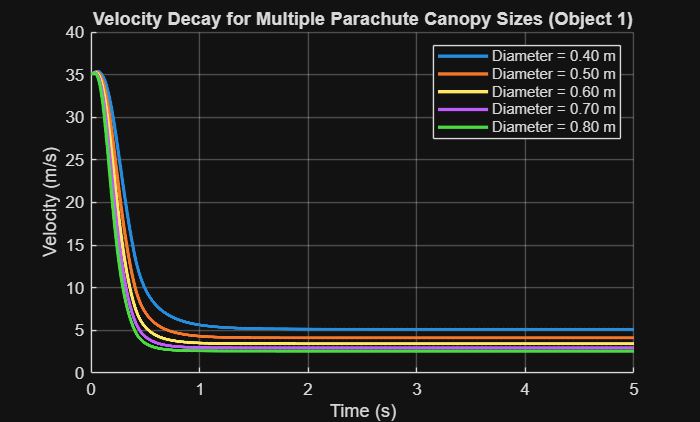

%%---------------------- PLOTS -------------------------
% Plot 1: Instantaneous shock
figure;
plot(time, Fi, 'LineWidth', 2);
grid on;
xlabel('Time (s)');
ylabel('Instantaneous Shock Force Fi (N)');
title('Opening Shock Force vs Time');
xlim([0 min(t0*3, 3)]);
% Plot 2: Velocity vs time
figure;
plot(time, V, 'LineWidth', 2); hold on
yline(desired_V, '--k', 'Desired Velocity');
if ~isnan(reached_idx)
    xline(time(reached_idx), '--r');
end
grid on;
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity Decay During Parachute Inflation');
xlim([0 min(3, t_end)]);
% Parachute Canopy 
clc
clear all
close all

% Object 1:
%% ----------- CONSTANT PARAMETERS ---------------------------------------
m       = 0.155;          % mass [kg]
Cd      = 0.75;         % drag coefficient
rho     = 1.225;        % air density
g       = 9.81;         % gravity
V0      = 35;           % initial downward velocity (m/s)
t_inf   = 0.40;         % inflation time (s)

%% ----------- CANOPY SIZES TO TEST --------------------------------------
diameters = [0.40, 0.50, 0.60, 0.70, 0.80];  % meters

%% ----------- SIMULATION PARAMETERS -------------------------------------
dt = 0.001;
t  = 0:dt:5;       % simulate first 5 seconds
N  = length(t);

%% ----------- PLOT SETUP -------------------------------------------------
figure; 
hold on; grid on;

colors = lines(length(diameters));   % auto-color set for clarity
legend_entries = strings(1, length(diameters));

%% ----------- LOOP THROUGH CANOPY SIZES ---------------------------------
for k = 1:length(diameters)

    D = diameters(k);              % current diameter
    A = pi * (D/2)^2;              % area
    
    V = zeros(1,N);
    V(1) = V0;

    % ---- Time Integration Loop ----
    for i = 1:N-1
        
        % Inflation model
        if t(i) < t_inf
            A_eff = A * (t(i)/t_inf)^2;  % quadratic inflation
        else
            A_eff = A;
        end
        
        Drag = 0.5 * rho * Cd * A_eff * V(i)^2;  % upward
        a = g - Drag/m;                          % downward positive
        
        % Update velocity
        V(i+1) = V(i) + a*dt;
        if V(i+1) < 0
            V(i+1) = 0;
        end
    end
    
    % ---- Plot for this canopy size ----
    plot(t, V, 'LineWidth', 2, 'Color', colors(k,:));
    legend_entries(k) = sprintf('Diameter = %.2f m', D);

end

%% ----------- Final Plot Settings ---------------------------------------
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity Decay for Multiple Parachute Canopy Sizes (Object 1)');
legend(legend_entries, 'Location', 'northeast');
hold off;

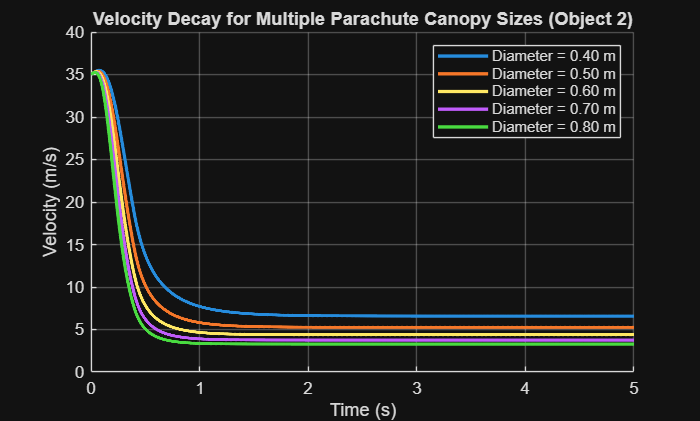


% Object 2:
%% ----------- CONSTANT PARAMETERS ---------------------------------------
m       = 0.255;          % mass [kg]
Cd      = 0.75;         % drag coefficient
rho     = 1.225;        % air density
g       = 9.81;         % gravity
V0      = 35;           % initial downward velocity (m/s)
t_inf   = 0.40;         % inflation time (s)
%% ----------- CANOPY SIZES TO TEST --------------------------------------
diameters = [0.40, 0.50, 0.60, 0.70, 0.80];  % meters
%% ----------- SIMULATION PARAMETERS -------------------------------------
dt = 0.001;
t  = 0:dt:5;       % simulate first 5 seconds
N  = length(t);
%% ----------- PLOT SETUP -------------------------------------------------
figure; 
hold on; grid on;
colors = lines(length(diameters));   % auto-color set for clarity
legend_entries = strings(1, length(diameters));
%% ----------- LOOP THROUGH CANOPY SIZES ---------------------------------
for k = 1:length(diameters)
    D = diameters(k);              % current diameter
    A = pi * (D/2)^2;              % area
    
    V = zeros(1,N);
    V(1) = V0;
    % ---- Time Integration Loop ----
    for i = 1:N-1
        
        % Inflation model
        if t(i) < t_inf
            A_eff = A * (t(i)/t_inf)^2;  % quadratic inflation
        else
            A_eff = A;
        end
        
        Drag = 0.5 * rho * Cd * A_eff * V(i)^2;  % upward
        a = g - Drag/m;                          % downward positive
        
        % Update velocity
        V(i+1) = V(i) + a*dt;
        if V(i+1) < 0
            V(i+1) = 0;
        end
    end
    
    % ---- Plot for this canopy size ----
    plot(t, V, 'LineWidth', 2, 'Color', colors(k,:));
    legend_entries(k) = sprintf('Diameter = %.2f m', D);
end
%% ----------- Final Plot Settings ---------------------------------------
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Velocity Decay for Multiple Parachute Canopy Sizes (Object 2)');
legend(legend_entries, 'Location', 'northeast');
hold off;

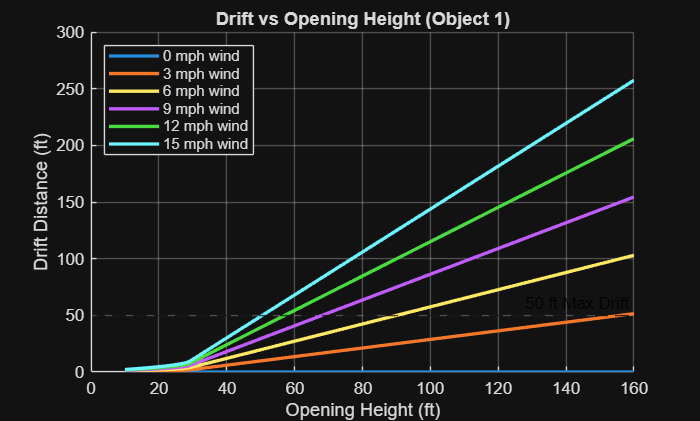

% Wind Effect on Parachute
clc
clear all
close all

% Object 1:
%% ---------------- CONSTANTS ----------------
g = 9.81;
ft2m = 0.3048;

target_radius_ft = 50;
target_radius_m  = target_radius_ft * ft2m;

drop_height_ft = 160;
drop_height_m  = drop_height_ft * ft2m;

%% ---------------- PARACHUTE PARAMETERS ----------------
m       = 0.155;       % kg
Cd      = 0.75;
rho     = 1.225;     % air density
D       = 0.58;      % canopy diameter (m)
A       = pi*(D/2)^2; % canopy area
t_inf   = 0.40;      % inflation duration (s)

% Initial freefall velocity at opening (from 150 ft)
V0 = sqrt(2*g*drop_height_m);

%% ---------------- WIND CONDITIONS ----------------
wind_speeds_mph = 0:3:15;
wind_speeds_mps = wind_speeds_mph * 0.447;

%% ---------------- OPENING HEIGHTS TO TEST ----------------
open_heights_ft = 10:1:160;
open_heights_m  = open_heights_ft * ft2m;

%% ---------------- PLOT SETUP ----------------------------
figure; hold on; grid on
colors = lines(length(wind_speeds_mps));
legend_entries = strings(length(wind_speeds_mps),1);

%% ========================================================================
%  MAIN LOOP – FOR EACH WIND SPEED
%% ========================================================================
for w = 1:length(wind_speeds_mps)

    wind = wind_speeds_mps(w);
    drift_total = zeros(size(open_heights_m));

    for h = 1:length(open_heights_m)

        h_open = open_heights_m(h);

        %% ---------------- SIMULATE INFLATION PHASE ----------------
        dt = 0.001;
        V = V0;
        h_remain = h_open;   % altitude remaining to ground
        t_elapsed = 0;
        drift = 0;

        while t_elapsed < t_inf && h_remain > 0

            % Effective area grows quadratically
            A_eff = A * (t_elapsed/t_inf)^2;

            % Drag (upward)
            Drag = 0.5 * rho * Cd * A_eff * V^2;

            % Downward acceleration
            a = g - Drag/m;

            % Update velocity
            V = V + a*dt;
            if V < 0, V = 0; end

            % Update altitude & drift
            h_remain = h_remain - V*dt;
            drift = drift + wind*dt;

            t_elapsed = t_elapsed + dt;
        end

        %% ---------------- FULLY DEPLOYED DESCENT ----------------
        if h_remain > 0
            % Now area = full A
            V_terminal = sqrt( (2*m*g) / (rho*Cd*A) );
            
            t_descent = h_remain / V_terminal;
            drift = drift + wind * t_descent;
            t_elapsed = t_elapsed + t_descent;
        end

        drift_total(h) = drift;  % store drift for this opening height
    end

    %% ---------------- PLOT DRIFT CURVE ----------------
    plot(open_heights_ft, drift_total/ft2m, ...
         'LineWidth', 2, 'Color', colors(w,:));

    legend_entries(w) = sprintf('%d mph wind', wind_speeds_mph(w));

end

%% ---------------- TARGET RADIUS LINE ----------------
yline(target_radius_ft, '--k', '50 ft Max Drift');

xlabel('Opening Height (ft)');
ylabel('Drift Distance (ft)');
title('Drift vs Opening Height (Object 1)');
legend(legend_entries, 'Location', 'northwest');
hold off


%% ========================================================================
%  FIND MAX SAFE OPENING HEIGHT AND TIME TO TOUCHDOWN
%% ========================================================================
fprintf("\n=== MAX SAFE OPENING HEIGHT + TIME TO TOUCHDOWN ===\n");


=== MAX SAFE OPENING HEIGHT + TIME TO TOUCHDOWN ===



for w = 1:length(wind_speeds_mps)

    wind = wind_speeds_mps(w);

    % Recompute drift for this wind (same logic as above but simpler)
    drift_total = zeros(size(open_heights_m));
    time_total  = zeros(size(open_heights_m));

    for h = 1:length(open_heights_m)
        
        h_open = open_heights_m(h);

        %% Inflation simulation
        dt = 0.001;
        V = V0;
        h_remain = h_open;
        t_elapsed = 0;
        drift = 0;

        while t_elapsed < t_inf && h_remain > 0
            A_eff = A * (t_elapsed/t_inf)^2;
            Drag  = 0.5 * rho * Cd * A_eff * V^2;
            a     = g - Drag/m;
            V     = max(0, V + a*dt);

            h_remain = h_remain - V*dt;
            drift    = drift + wind*dt;

            t_elapsed = t_elapsed + dt;
        end

        %% Full descent
        if h_remain > 0
            V_terminal = sqrt( (2*m*g) / (rho*Cd*A) );
            t_descent  = h_remain / V_terminal;
            drift      = drift + wind*t_descent;
            t_elapsed  = t_elapsed + t_descent;
        end

        drift_total(h) = drift;
        time_total(h)  = t_elapsed;
    end

    % Find all safe opening heights
    valid_idx = find(drift_total <= target_radius_m);

    if isempty(valid_idx)
        fprintf("%2d mph wind: No safe opening height.\n", wind_speeds_mph(w));
    else
        max_safe_h_ft = open_heights_ft(valid_idx(end));
        time_touchdown = time_total(valid_idx(end));

        fprintf("%2d mph wind: Open at %.1f ft → Touchdown in %.2f sec\n", ...
            wind_speeds_mph(w), max_safe_h_ft, time_touchdown);
    end
end

 0 mph wind: Open at 160.0 ft → Touchdown in 11.70 sec
 3 mph wind: Open at 156.0 ft → Touchdown in 11.36 sec
 6 mph wind: Open at 90.0 ft → Touchdown in 5.67 sec
 9 mph wind: Open at 68.0 ft → Touchdown in 3.78 sec
12 mph wind: Open at 57.0 ft → Touchdown in 2.83 sec
15 mph wind: Open at 50.0 ft → Touchdown in 2.23 sec


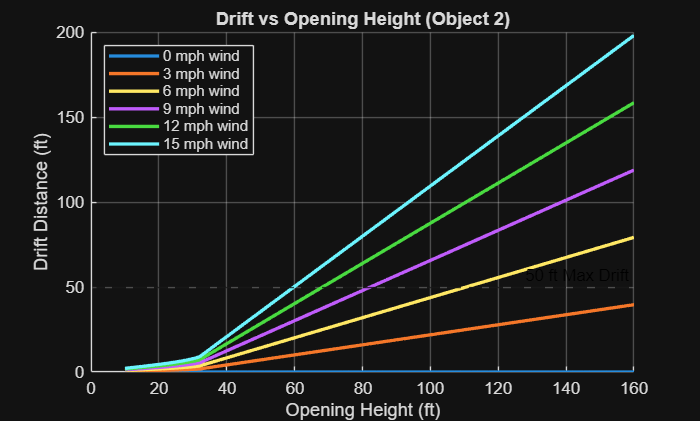


% Object 2:
%% ---------------- CONSTANTS ----------------
g = 9.81;
ft2m = 0.3048;

target_radius_ft = 50;
target_radius_m  = target_radius_ft * ft2m;

drop_height_ft = 160;
drop_height_m  = drop_height_ft * ft2m;

%% ---------------- PARACHUTE PARAMETERS ----------------
m       = 0.255;       % kg
Cd      = 0.75;
rho     = 1.225;     % air density
D       = 0.58;      % canopy diameter (m)
A       = pi*(D/2)^2; % canopy area
t_inf   = 0.40;      % inflation duration (s)

% Initial freefall velocity at opening (from 150 ft)
V0 = sqrt(2*g*drop_height_m);

%% ---------------- WIND CONDITIONS ----------------
wind_speeds_mph = 0:3:15;
wind_speeds_mps = wind_speeds_mph * 0.447;

%% ---------------- OPENING HEIGHTS TO TEST ----------------
open_heights_ft = 10:1:160;
open_heights_m  = open_heights_ft * ft2m;

%% ---------------- PLOT SETUP ----------------------------
figure; hold on; grid on
colors = lines(length(wind_speeds_mps));
legend_entries = strings(length(wind_speeds_mps),1);

%% ========================================================================
%  MAIN LOOP – FOR EACH WIND SPEED
%% ========================================================================
for w = 1:length(wind_speeds_mps)

    wind = wind_speeds_mps(w);
    drift_total = zeros(size(open_heights_m));

    for h = 1:length(open_heights_m)

        h_open = open_heights_m(h);

        %% ---------------- SIMULATE INFLATION PHASE ----------------
        dt = 0.001;
        V = V0;
        h_remain = h_open;   % altitude remaining to ground
        t_elapsed = 0;
        drift = 0;

        while t_elapsed < t_inf && h_remain > 0

            % Effective area grows quadratically
            A_eff = A * (t_elapsed/t_inf)^2;

            % Drag (upward)
            Drag = 0.5 * rho * Cd * A_eff * V^2;

            % Downward acceleration
            a = g - Drag/m;

            % Update velocity
            V = V + a*dt;
            if V < 0, V = 0; end

            % Update altitude & drift
            h_remain = h_remain - V*dt;
            drift = drift + wind*dt;

            t_elapsed = t_elapsed + dt;
        end

        %% ---------------- FULLY DEPLOYED DESCENT ----------------
        if h_remain > 0
            % Now area = full A
            V_terminal = sqrt( (2*m*g) / (rho*Cd*A) );
            
            t_descent = h_remain / V_terminal;
            drift = drift + wind * t_descent;
            t_elapsed = t_elapsed + t_descent;
        end

        drift_total(h) = drift;  % store drift for this opening height
    end

    %% ---------------- PLOT DRIFT CURVE ----------------
    plot(open_heights_ft, drift_total/ft2m, ...
         'LineWidth', 2, 'Color', colors(w,:));

    legend_entries(w) = sprintf('%d mph wind', wind_speeds_mph(w));

end

%% ---------------- TARGET RADIUS LINE ----------------
yline(target_radius_ft, '--k', '50 ft Max Drift');

xlabel('Opening Height (ft)');
ylabel('Drift Distance (ft)');
title('Drift vs Opening Height (Object 2)');
legend(legend_entries, 'Location', 'northwest');
hold off


%% ========================================================================
%  FIND MAX SAFE OPENING HEIGHT AND TIME TO TOUCHDOWN
%% ========================================================================
fprintf("\n=== MAX SAFE OPENING HEIGHT + TIME TO TOUCHDOWN ===\n");


=== MAX SAFE OPENING HEIGHT + TIME TO TOUCHDOWN ===



for w = 1:length(wind_speeds_mps)

    wind = wind_speeds_mps(w);

    % Recompute drift for this wind (same logic as above but simpler)
    drift_total = zeros(size(open_heights_m));
    time_total  = zeros(size(open_heights_m));

    for h = 1:length(open_heights_m)
        
        h_open = open_heights_m(h);

        %% Inflation simulation
        dt = 0.001;
        V = V0;
        h_remain = h_open;
        t_elapsed = 0;
        drift = 0;

        while t_elapsed < t_inf && h_remain > 0
            A_eff = A * (t_elapsed/t_inf)^2;
            Drag  = 0.5 * rho * Cd * A_eff * V^2;
            a     = g - Drag/m;
            V     = max(0, V + a*dt);

            h_remain = h_remain - V*dt;
            drift    = drift + wind*dt;

            t_elapsed = t_elapsed + dt;
        end

        %% Full descent
        if h_remain > 0
            V_terminal = sqrt( (2*m*g) / (rho*Cd*A) );
            t_descent  = h_remain / V_terminal;
            drift      = drift + wind*t_descent;
            t_elapsed  = t_elapsed + t_descent;
        end

        drift_total(h) = drift;
        time_total(h)  = t_elapsed;
    end

    % Find all safe opening heights
    valid_idx = find(drift_total <= target_radius_m);

    if isempty(valid_idx)
        fprintf("%2d mph wind: No safe opening height.\n", wind_speeds_mph(w));
    else
        max_safe_h_ft = open_heights_ft(valid_idx(end));
        time_touchdown = time_total(valid_idx(end));

        fprintf("%2d mph wind: Open at %.1f ft → Touchdown in %.2f sec\n", ...
            wind_speeds_mph(w), max_safe_h_ft, time_touchdown);
    end
end

 0 mph wind: Open at 160.0 ft → Touchdown in 9.00 sec
 3 mph wind: Open at 160.0 ft → Touchdown in 9.00 sec
 6 mph wind: Open at 110.0 ft → Touchdown in 5.65 sec
 9 mph wind: Open at 82.0 ft → Touchdown in 3.77 sec
12 mph wind: Open at 68.0 ft → Touchdown in 2.83 sec
15 mph wind: Open at 59.0 ft → Touchdown in 2.22 sec
